% read in a default audio file
[s, Fs] = audioread('guitartune.wav');
s = s'

s =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


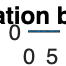

plot(0:length(s)-1,s);
grid; axis([0 length(s)-1 -2 2]);
title('The information bearing signal');

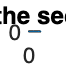

% uncomment to play guitar sound
% sound(s, Fs)

nvar  = 1.0;                  % Noise variance
noise = (randn(length(s),1)*nvar)';   % White noise
plot(0:length(s)-1,noise);
title('Noise picked up by the secondary microphone');
grid; axis([0 1000 -4 4]);


% use some window filter... chebyshev? idk what numbers we want
lp = dsp.FIRFilter('Numerator',fir1(31,0.5));% Low pass FIR filter
[b, a] = fir1(31,0.5)

b =    -0.0012   -0.0014    0.0020    0.0029   -0.0044   -0.0064    0.0090    0.0125   -0.0169   -0.0227    0.0305    0.0412   -0.0573   -0.0850    0.1472    0.4501    0.4501    0.1472   -0.0850   -0.0573    0.0412    0.0305   -0.0227   -0.0169    0.0125    0.0090   -0.0064   -0.0044    0.0029    0.0020   -0.0014   -0.0012


a = 1

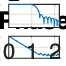

freqz(b, a, [], Fs)


% filter, put in transfer function and noise (with designated var)
filtered_noise = lp(noise)

filtered_noise =     0.0011    0.0009   -0.0003   -0.0019   -0.0032    0.0006    0.0006   -0.0021    0.0018   -0.0002   -0.0002   -0.0014    0.0002    0.0011    0.0009    0.0006    0.0002   -0.0008   -0.0015    0.0007   -0.0001    0.0009    0.0011    0.0002   -0.0005    0.0003   -0.0003   -0.0001   -0.0011    0.0015   -0.0006   -0.0001   -0.0002    0.0005   -0.0013    0.0005    0.0014   -0.0009   -0.0019   -0.0002    0.0005   -0.0003   -0.0006    0.0010   -0.0019   -0.0002    0.0002   -0.0015    0.0006   -0.0005



% signal plus noise
signal_plus_noise = filtered_noise + s

signal_plus_noise =     0.0011    0.0009   -0.0003   -0.0019   -0.0032    0.0006    0.0006   -0.0021    0.0018   -0.0002   -0.0002   -0.0014    0.0002    0.0011    0.0009    0.0006    0.0002   -0.0008   -0.0015    0.0007   -0.0001    0.0009    0.0011    0.0002   -0.0005    0.0003   -0.0003   -0.0001   -0.0011    0.0015   -0.0006   -0.0001   -0.0002    0.0005   -0.0013    0.0005    0.0014   -0.0009   -0.0019   -0.0002    0.0005   -0.0003   -0.0006    0.0010   -0.0019   -0.0002    0.0002   -0.0015    0.0006   -0.0005



% uncomment for sound of signal plus noise
% sound(signal_plus_noise, Fs)

D = s;
A = signal_plus_noise;

n = numel(D);

M = 25;
w = zeros(M,1);
wi = zeros(M,1);
R = [];
k = 1;
r = xcorr(A)

r = 1.0e+03 *

   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


rr = [];

for i = 1:1:M
    rr(i) = r(n-i+1);
end

R = toeplitz(rr);
ei = max(eig(R));
u = 1/ei;

for i = 1:1:M
    P(i) = r(n-i+1);
end

for i = 1:10
    wi = w + u*(P'-R*w);
    w = wi;
end

% find the estimate
Est = zeros(n, 1)

Est =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


for i = M:n
    j = A(i:-1:i-M+1);
    Est(i) = (wi)'*(j)';
end

% error signal
Err = Est' - D;

sound(Est, Fs)
